# Potential Fields in 3 Joint Space

`By Brian Lesko, Graduate Researcher and Teaching Associate, Masters of mechanical engineering student `

`For Robotics Project | Robotics 7752 | 11/29/2022`

clc; clear; close all;

# Using the Stanford Robot Architecture RRP

[Slist,Mlist_joints] = getdVRKArchitecture();
theta = [pi/3 pi/3 .5]';

# A Robot Configuration described by a set of occupied points xyz

    % Forward Kinematics to find all joint locations 
    jointLocations = getJointLocations(Slist(:,1:3),Mlist_joints,theta);

    % add n points lying between each joint on their respective link
    n = 3; % Test Points per Link
    configurationPoints = getConfigurationPoints(jointLocations,n);

    % the 1st two joints of the dVRK are overlapping, throw out points from the "link" between them
    configurationPoints = configurationPoints(3:length(configurationPoints(:,1)),:);

# Get potential of configuration with respect to an obstacle

a sum of distances between robot points and an obstacle surface

obstacle = [.04 .04 -.1 .02];
potential = getObstaclePotentialAtConfigurationPoints(configurationPoints,obstacle)

potential = 178.2492

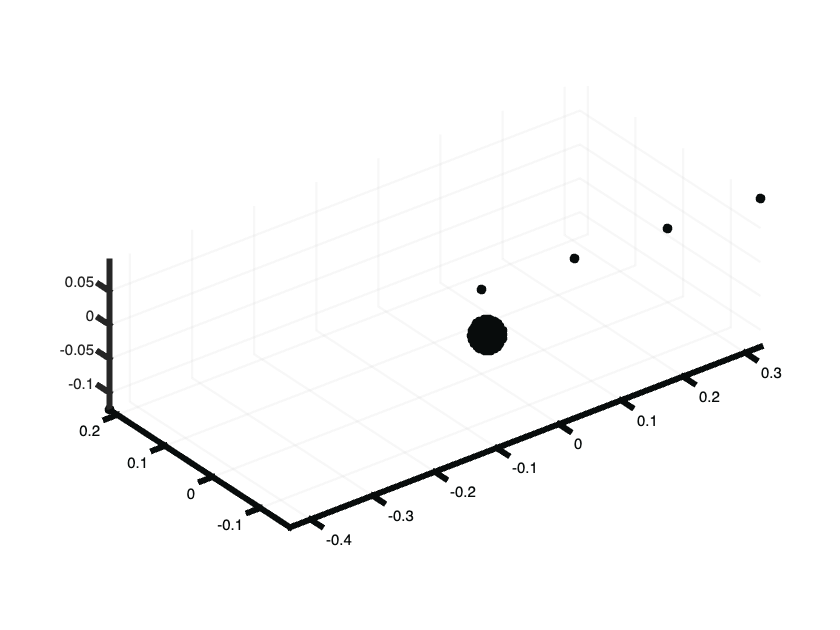

plotMesh(configurationPoints); hold on
sphereMesh = getSphereMesh(obstacle(1:3)',obstacle(4),10);
plotMesh(sphereMesh); hold off

# Repeat for all Obstacles, sum 

obstacles = [[1 1 1 0];[2 2 2 0]];

potentials = zeros(length(obstacles(:,1)),1);
for i = 1:1:length(obstacles(:,1))
    potentials(i) = getObstaclePotentialAtConfigurationPoints(configurationPoints,obstacles(i,:));
end 
potential = sum(potentials)

potential = 2.1074

# Unobstructed Configuration Space of the Robot

described by gridded points, specific for RRP

nGridPoints = 20;
jointMaxes = [[50 50]*pi/180 .15];
jointMins = [[-50 -50]*pi/180 .028];
thetas = getCSpacePermutations(nGridPoints,jointMaxes,jointMins);

# The Obstacle Potential Field

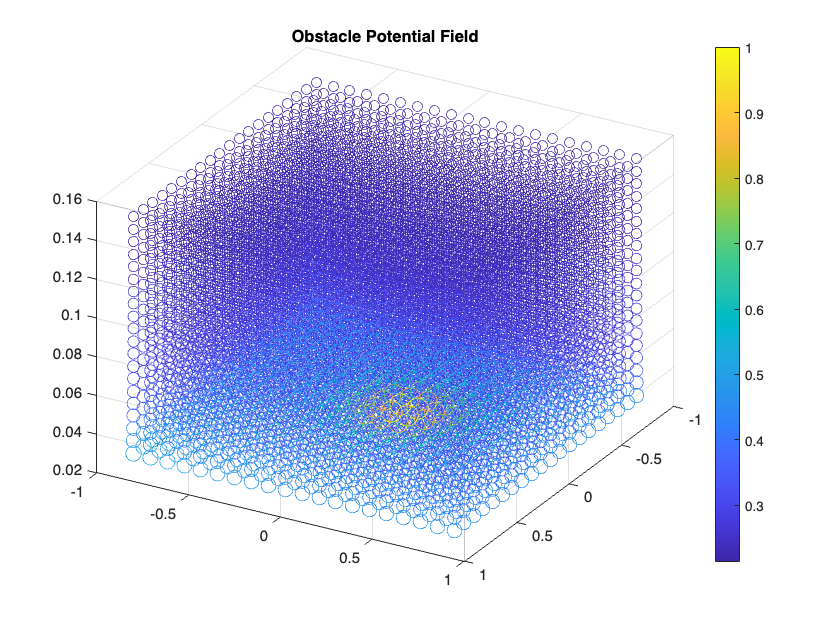

obstacles = [[.004 0 -.022 0];[.004 0.004 -.01 0]];
thetaMesh = thetas;
obstaclePotentialField = getObstaclePotentialField(Slist(:,1:3),Mlist_joints,thetaMesh,obstacles);
obP = obstaclePotentialField;
scatter3(obP(:,1),obP(:,2),obP(:,3),200*obP(:,4),obP(:,4),'o'),colorbar
view([-29.671 -33.270]), title('Obstacle Potential Field')

An Obstacle Potential Field can be combined with a goal potential field to create a robot trajectory toward a goal while incentivising motion around obstacles

# Goal Position Potential Field 

goalTheta =    -2.4088    0.5896    0.0939


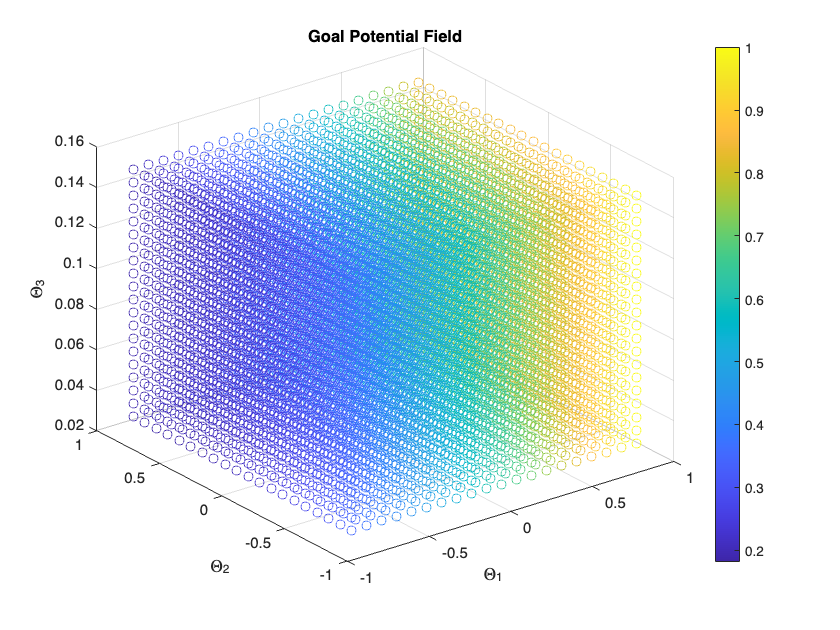

goalPotentialField =    -0.8727   -0.8727    0.0280    0.3487    1.0000    1.0000    1.0000
   -0.8727   -0.8727    0.0344    0.3487    1.0000    1.0000    2.0000
   -0.8727   -0.8727    0.0408    0.3486    1.0000    1.0000    3.0000
   -0.8727   -0.8727    0.0473    0.3486    1.0000    1.0000    4.0000
   -0.8727   -0.8727    0.0537    0.3485    1.0000    1.0000    5.0000
   -0.8727   -0.8727    0.0601    0.3485    1.0000    1.0000    6.0000
   -0.8727   -0.8727    0.0665    0.3484    1.0000    1.0000    7.0000
   -0.8727   -0.8727    0.0729    0.3484    1.0000    1.0000    8.0000
   -0.8727   -0.8727    0.0794    0.3484    1.0000    1.0000    9.0000
   -0.8727   -0.8727    0.0858    0.3484    1.0000    1.0000   10.0000


goalPosition = [.045 .045 -.05];
M3 = Mlist_joints(:,:,1)*Mlist_joints(:,:,2)*Mlist_joints(:,:,3);
goalPotentialField = getGoalPotentialField(goalPosition,M3,Slist,nGridPoints)

# Combining the Fields

changing the weights

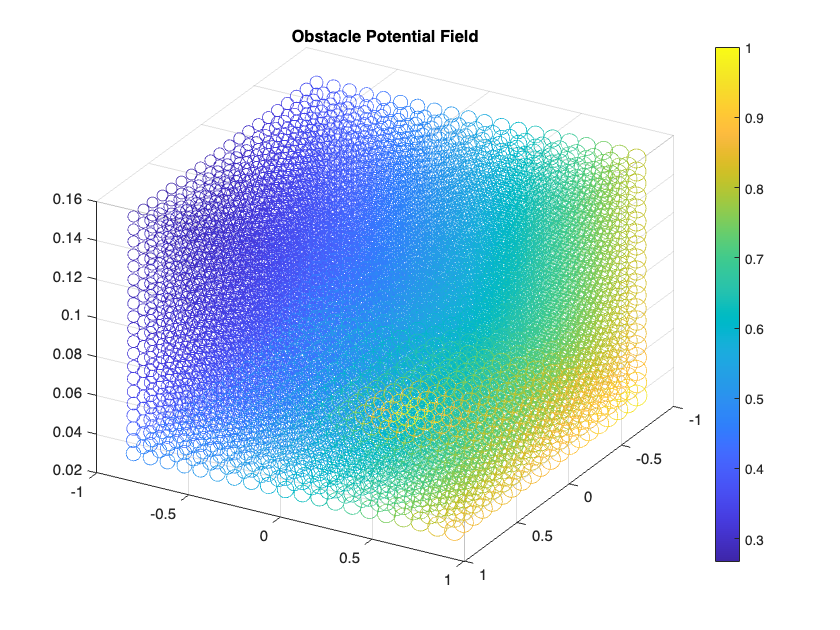

potentialField = obstaclePotentialField;
potentialField(:,4) = 3*obstaclePotentialField(:,4) + 3*goalPotentialField(:,4);
potentialField(:,4) = potentialField(:,4)/max(potentialField(:,4));
P = potentialField;
scatter3(P(:,1),P(:,2),P(:,3),200*P(:,4),P(:,4),'o'),colorbar
view([-29.671 -33.270]), title('Obstacle Potential Field')

# Creating a Gradient from the Combined Potentials 

Reshape

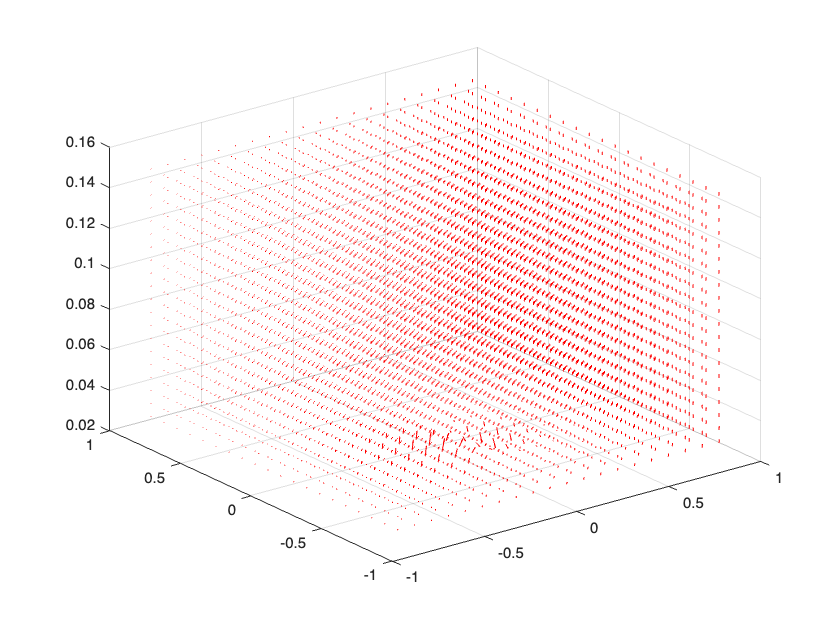

gradientField =    -0.8727   -0.8727    0.0280    0.5369   -0.0066   -0.0197    0.0076
   -0.8727   -0.8727    0.0344    0.5003   -0.0065   -0.0157    0.0067
   -0.8727   -0.8727    0.0408    0.4741   -0.0063   -0.0108    0.0062
   -0.8727   -0.8727    0.0473    0.4548   -0.0061   -0.0077    0.0060
   -0.8727   -0.8727    0.0537    0.4401   -0.0059   -0.0058    0.0058
   -0.8727   -0.8727    0.0601    0.4285   -0.0058   -0.0044    0.0058
   -0.8727   -0.8727    0.0665    0.4193   -0.0057   -0.0035    0.0057
   -0.8727   -0.8727    0.0729    0.4118   -0.0056   -0.0028    0.0057
   -0.8727   -0.8727    0.0794    0.4056   -0.0055   -0.0023    0.0056
   -0.8727   -0.8727    0.0858    0.4004   -0.0054   -0.0019    0.0056


gradientField = getGradientField(potentialField)

# Creating a Path through the Gradient Field

using the control law: 

startPosition = [0 0 0.05];
goalTheta = IKinSpace(Slist(:,1:3), M3, getTOrthogonal(goalPosition'), [0 0 0]', .0005, .0005)

goalTheta =     1.0637
    2.4752
   -0.0809


trajectory = getPathThroughGradientField(startPosition,gradientField,goalTheta)

trajectory =          0         0    0.0500
   -0.0033   -0.0131    0.0616
   -0.0061   -0.0186    0.0724
   -0.0089   -0.0217    0.0829
   -0.0116   -0.0237    0.0933
   -0.0143   -0.0253    0.1035
   -0.0169   -0.0265    0.1136
   -0.0196   -0.0275    0.1237
   -0.0222   -0.0283    0.1338
   -0.0249   -0.0290    0.1438


# Animating the Produced Motion

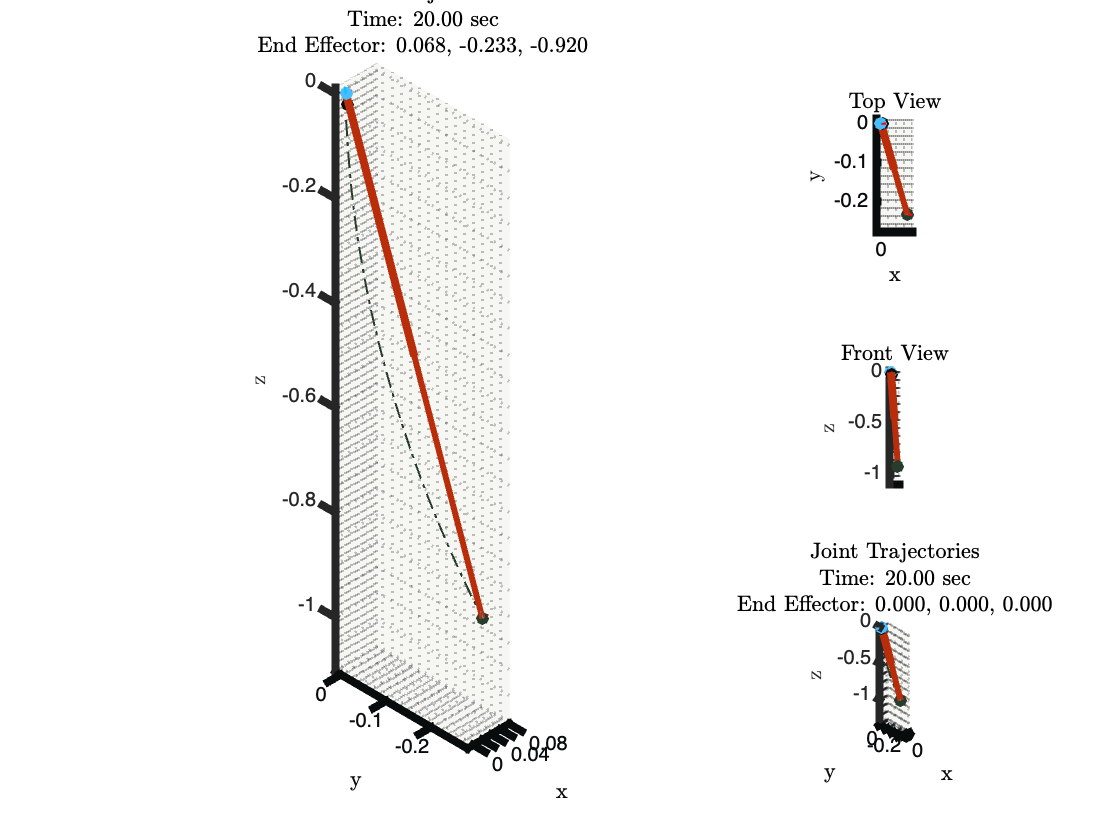

timeTotal = 20;
filename = 'gifBABY.gif';
sphereMesh1 = getSphereMesh(obstacles(1,1:3)',obstacles(1,4),10);
sphereMesh2 = getSphereMesh(obstacles(1,1:3)',obstacles(1,4),10);
pointMesh = [sphereMesh1;sphereMesh2];
animateRobot4(trajectory,timeTotal,Slist,Mlist_joints,filename,pointMesh)

# **Functions **

# New Functions

make a Gradient Field

function gradientField = getGradientField(potentialField)
    nGridPoints = ceil(length(potentialField(:,1))^(1/3));
    size = [nGridPoints,nGridPoints,nGridPoints];
    cube = reshape(potentialField(:,4),size);
    [fx,fy,fz] = gradient(cube);
    size = [nGridPoints^3 1];
    fx = reshape(fx,size);fy = reshape(fy,size);fz = reshape(fz,size);
    weight = 1*potentialField(:,4); 
    gradientField = [potentialField(:,1:4),weight.*fx,weight.*fy,weight.*fz];
    gf = gradientField;
    quiver3(gf(:,1),gf(:,2),gf(:,3),gf(:,5),gf(:,6),gf(:,7),'r')
end 

Path Through Gradient Field

function trajectory = getPathThroughGradientField(p,gradient,goalTheta)
    % By Morgan Strauss 12/11/22
    % Adapted by Brian Lesko 12/11/22
    %Inputs: p - starting position (js), gradient - gradient that you want to follow
    %Outputs: trajectory - overall trajectory after following gradient
    i =1;
    e = 0.02*(0.15-0028);
    while(norm(p-goalTheta)>e && i < 100) %Set precision based on theta3 bounds
        trajectory(i,:) = p;
        row = findClosest(p,gradient);
        push = gradient(row,5:7);
        p = p + gradient(row,5:7);
        i = i+1;
    end
end
function row = findClosest(p,gradient)
    tol = 10000;
    for i = 1:length(gradient(:,1))
        if norm(gradient(i,1:3)-p) < tol
            row = i;
            tol = norm(gradient(i,1:3)-p);
        end
    end
end

Get Goal Potential Field 

function [goalP] = getGoalPotentialField(p_end,M3,Slist,n)
    % Authored by Morgan Strauss 12/10/22
    % Modified by Brian Lesko 12/10/22
    %%Potential field calculation
    % Tabulate potential field in a gridded joint space
    theta_1_test = linspace(-50,50,n)*pi/180;
    theta_2_test = linspace(-50,50,n)*pi/180;
    theta_3_test = linspace(0.028,0.15,n);
    % define goal theta values
    goalTheta = analyticalInverseKinematicsRRP(M3,Slist(:,1:3),p_end)
    %Assign Obstacle Potential Scale:
    goalP = [];
    for i = 1:length(theta_1_test)
        for j = 1:length(theta_2_test)
            for h = 1:length(theta_3_test)
            % goal field is the minimum squared distance to the nearest inverse
            % kinematics solution
            theta = [theta_1_test(i); theta_2_test(j); theta_3_test(h)];
            P = norm(theta-goalTheta')^2;
            %Put all output values together:
            rowP = [theta_1_test(i) theta_2_test(j) theta_3_test(h) P i j h];
            goalP = [goalP; rowP];
            end
        end
    end
    goalP(:,4) = goalP(:,4)./max(goalP(:,4));
    scatter3(goalP(:,1),goalP(:,2),goalP(:,3),[],goalP(:,4),'o','MarkerFaceAlpha',0.2);
    xlabel('\Theta_1'), ylabel('\Theta_2'), zlabel('\Theta_3'), title('Goal Potential Field')
    colorbar
end

Combine Obstacle Potential Fields Work 

function obstaclePotentialField = getObstaclePotentialField(Slist,Mlist_joints,thetaMesh,obstacles)
    obstaclePotentialField = thetaMesh;
    for i = 1:1:length(thetaMesh(:,1))
        theta = thetaMesh(i,1:3)';
        jointLocations = getJointLocations(Slist(:,1:3),Mlist_joints,theta);
        n = 3; % Test Points per Link
        configurationPoints = getConfigurationPoints(jointLocations,n);
        % because this is the dVRK architecture, there is no link between R, R
        configurationPoints = configurationPoints(3:length(configurationPoints(:,1)),:);

        potentials = zeros(length(obstacles(:,1)),1);
        for j = 1:1:length(obstacles(:,1))
            potentials(j) = getObstaclePotentialAtConfigurationPoints(configurationPoints,obstacles(j,:));
        end 
        obstaclePotentialField(i,4) = sum(potentials);
    end 
    % Normalized to 1
    obstaclePotentialField(:,4) = obstaclePotentialField(:,4)/max(obstaclePotentialField(:,4));
end

C Space joint Permutations list with indicies for searching 

function thetas = getCSpacePermutations(gridPoints,jointMaxes,jointMins)
    % Making Theta Vectors
    jointNum = length(jointMaxes(1,:));
    thetaVecs = zeros(gridPoints,jointNum);
    for j = 1:1:jointNum
        thetaVecs(:,j) = linspace(jointMins(j),jointMaxes(j),gridPoints);
    end 

    thetas =[];
    for i = 1:1:gridPoints
        for j = 1:1:gridPoints
            for k = 1:1:gridPoints
                theta = [thetaVecs(i,1) thetaVecs(j,2) thetaVecs(k,3)];
                thetaIndicies = [theta,[0,i,j,k]];
                thetas = [thetas; thetaIndicies];
            end 
        end 
    end
end 

get Obstacle Potential Field 

function potential = getObstaclePotentialAtConfigurationPoints(configurationPoints,obstacle)
    numTestLocations = length(configurationPoints(:,1));
    distances = zeros(numTestLocations,1);
    for i = 1:1:numTestLocations
        testLocation = configurationPoints(i,:);
        obstacleLocation = obstacle(1:3);
        radius = obstacle(4);
        distances(i) = norm(testLocation-obstacleLocation) - radius;
    end 
    potential = sum(1./distances.^2);
end 

Get Joint Locations

function jointLocations = getJointLocations(Slist,Mlist_joints,theta)
jointLocations = zeros(length(Slist(1,:)),3);
    for n = 1:1:length(Slist(1,:))
        T = customForwardKinematics(Mlist_joints,Slist,n,theta);
        [~,p] = TransToRp(T); %the nth joint position at t is p
        jointLocations(n,:) = p;
    end 
end

get Configuration Points of a robot, joint locations and n sampled Points on each link

function pointMesh = getConfigurationPoints(jointLocations,n)
    linkNumber = length(jointLocations(:,1))-1;
    for i = 1:1:linkNumber %for each link
        currentJointLocation = jointLocations(i,:);
        nextJointLocation = jointLocations(i+1,:);
        vector = currentJointLocation-nextJointLocation;
      
        for m = 0:1:n
            pointMesh(i+m+1,:) = currentJointLocation + m*vector/(n+1);
        end 
    end 
    % The End effector location
    pointMesh = [pointMesh;jointLocations(length(jointLocations(:,1)),:)];
end 

# Past Work Functions

function drawAxis(T,darkness,size)
% Original Author: Brian Lesko 11/24/22
% Revised 11/30/22 by Brian Lesko

%Axis Colors
f = 1+darkness; %Darkness should be from 0 to 1
color = [ [182, 2, 8]/182/f ; [59, 114, 29]/114/f ; [4, 110, 143]/143/f ];

location = T(1:3,4);
orientation = T(1:3,1:3);

%plotting 3 vectors
    for i = 1:1:3
        vec = orientation(:,i)*size;
        quiver3(location(1),location(2),location(3),vec(1),vec(2),vec(3),'LineWidth',2,'Color',color(i,:));
    end 
end
function Torthogonal = getTOrthogonal(origin)
    z = (origin/norm(origin));
    x = cross([0 0 1]',z);
    x = x/norm(x);
    y = cross(z,x);
    y = y/norm(y);
    orientation = [x y z];
    Torthogonal = [orientation,origin ; [0 0 0 1]];
end 

Analytical IK

function thetaMesh = analyticalInverseKinematicsRRP(M,Slist,mesh)
% mesh is a list of points x,y,z nx3
% thetaMesh is the configuration space corresponding to each point
% Theta 3 Prismatic Offset
pOffset = .013; % mm 
    thetaMesh = zeros(length(mesh(:,1)),3);
    for i = 1:1:length(mesh(:,1))
        p = mesh(i,:)';
        T = getTOrthogonal(p);
        eul = rotm2eul(T(1:3,1:3),'XYZ');
        th3 = norm(p)+pOffset; %because S3 is defined as negative 
        thetaList = [[eul(1) eul(2)] th3];
        % simplify Angle, maybe not needed
        for g = 1:1:length(thetaList)
            if thetaList(g)>pi
                thetaList(g) = thetaList(g)-2*pi; end
            if thetaList(g)<-pi
                    thetaList(g) = thetaList(g)+2*pi; end 
        end 
        % Forward Kinematics to Check Validity
        thetaMesh(i,:) = thetaList(1:3);
    end 
end 

get Sphere Mesh

function mesh = getSphereMesh(location,radius,n)
%Inputs: radius in meters, location as a 3x1 vector in meters
% note that meshes are plotted with with the surf object
    [X,Y,Z] = sphere(n); % nominal sphere radius 1, location 0,0,0

    %Scale the sphere to the radius specified
    X = X * radius; Y = Y * radius; Z = Z * radius;

    %Translate the sphere to the location specificied 
    X = X + location(1); Y = Y + location(2); Z = Z + location(3);

    %reshape the mesh
    vertexNumber = length(X(1,:));
    Xlist = reshape(X,[vertexNumber^2,1]); 
    Ylist = reshape(Y,[vertexNumber^2,1]); 
    Zlist = reshape(Z,[vertexNumber^2,1]); 
    mesh = [Xlist Ylist Zlist];
end 

Plot Mesh and figure settings

function fig = plotMesh(mesh)
    fig = scatter3(mesh(:,1),mesh(:,2),mesh(:,3)); plotSetting(fig);
end 
function plotSetting(fig)
    richBlackHex = '#080C0C'; white = '#F6F5F5';
    ax = gca; % Get handle to current axes.
    % Grid
    ax. GridAlpha = 0.03; % Make grid lines less transparent.
    ax. GridColor = richBlackHex; 
    ax.Box = 'off';
    % Axis
    ax. LineWidth = 1.5;
    ax. YAxis.LineWidth = 4; ax.XAxis.LineWidth = 4; ax.ZAxis.LineWidth = 4;
    ax.XColor = richBlackHex; % Red.
    ax.YColor = richBlackHex; % Blue.
    axis equal
    % Figure
    fig.MarkerEdgeColor = richBlackHex;
    fig.MarkerFaceColor = richBlackHex;
    %Labels
end 

Forward Kinematics Custom Call

function Tnow = customForwardKinematics(Mlist_joints,Slist,n,theta_now)
    %Reformatting inputs for compatibility with Modern Robotics code
    M = eye(4);
    for i = 1:1:n
        M = Mlist_joints(:,:,n) * M; %M is then equal to the M0n
    end 
    S = Slist(:,1:n); %Slist from joint 1 to n 
    theta = theta_now(1:n); %theta from joint 1 to n
    Tnow = FKinSpace(M,S,theta); %the current joints transformation
end 

dVRK Architecture

function [Slist Mlist_joints] = getdVRKArchitecture()
    %meters
    S1 = [1 0 0 0 0 0]; % joint 1 rotates about the x axis
    S2 = [0 1 0 0 0 0]; % joint 2 rotates about the y axis
    S3 = [0 0 0 0 0 -1]; % joint 3 translates in the -z axis 
    S4 = [0 0 -1 0 0 0]; % joint 4 rotates about the z axis 
    S5 = [0 1 0 -0.0091 0 0]; %S5 = [0 1 0 -0.91 0 0];
    S6 = [1 0 0 0 0 0];
    Slist = [S1' S2' S3' S4' S5' S6'];

    %MLIST JOINTS
    M01 = [eye(3) [0; 0; 0]; zeros(1,3) 1]; 
    M12 = [eye(3) [0; 0; 0]; zeros(1,3) 1]; 
    M23 = [eye(3) [0; 0; 0]; zeros(1,3) 1]; 
    M34 = [eye(3) [0; 0; 0]; zeros(1,3) 1]; 
    M45 = [eye(3) [0; 0; -0.0091]; zeros(1,3) 1]; 
    M56 = [eye(3) [0; 0; 0]; zeros(1,3) 1]; 
    Mlist_joints = cat(3,M01,M12,M23,M34,M45,M56);
end 

# Modern Robotics Textbook Functions

function [thetalist, success] ...
         = IKinSpace(Slist, M, T, thetalist0, eomg, ev)
% *** CHAPTER 6: INVERSE KINEMATICS ***
% Takes Slist: The joint screw axes in the space frame when the manipulator
%              is at the home position, in the format of a matrix with the
%              screw axes as the columns,
%       M: The home configuration of the end-effector,
%       T: The desired end-effector configuration Tsd,
%       thetalist0: An initial guess of joint angles that are close to 
%                   satisfying Tsd,
%       eomg: A small positive tolerance on the end-effector orientation 
%             error. The returned joint angles must give an end-effector 
%             orientation error less than eomg,
%       ev: A small positive tolerance on the end-effector linear position 
%           error. The returned joint angles must give an end-effector 
%           position error less than ev.
% Returns thetalist: Joint angles that achieve T within the specified 
%                    tolerances,
%         success: A logical value where TRUE means that the function found
%                  a solution and FALSE means that it ran through the set 
%                  number of maximum iterations without finding a solution
%                  within the tolerances eomg and ev.
% Uses an iterative Newton-Raphson root-finding method.
% The maximum number of iterations before the algorithm is terminated has 
% been hardcoded in as a variable called maxiterations. It is set to 20 at 
% the start of the function, but can be changed if needed.  
thetalist = thetalist0;
i = 0;
maxiterations = 20;
Tsb = FKinSpace(M, Slist, thetalist);
Vs = Adjoint(Tsb) * se3ToVec(MatrixLog6(TransInv(Tsb) * T));
err = norm(Vs(1: 3)) > eomg || norm(Vs(4: 6)) > ev;
while err && i < maxiterations
    thetalist = thetalist + pinv(JacobianSpace(Slist, thetalist)) * Vs;
    i = i + 1;
    Tsb = FKinSpace(M, Slist, thetalist);
    Vs = Adjoint(Tsb) * se3ToVec(MatrixLog6(TransInv(Tsb) * T));
    err = norm(Vs(1: 3)) > eomg || norm(Vs(4: 6)) > ev;
end
success = ~ err;
end
function T = FKinSpace(M, Slist, thetalist)
% *** CHAPTER 4: FORWARD KINEMATICS ***
% Takes M: the home configuration (position and orientation) of the 
%          end-effector,
%       Slist: The joint screw axes in the space frame when the manipulator
%              is at the home position,
%       thetalist: A list of joint coordinates.
% Returns T in SE(3) representing the end-effector frame, when the joints 
% are at the specified coordinates (i.t.o Space Frame).
T = M;
for i = size(thetalist): -1: 1
    T = MatrixExp6(VecTose3(Slist(:, i) * thetalist(i))) * T;
end
function se3mat = VecTose3(V)
% *** CHAPTER 3: RIGID-BODY MOTIONS ***
% Takes a 6-vector (representing a spatial velocity).
% Returns the corresponding 4x4 se(3) matrix.
se3mat = [VecToso3(V(1: 3)), V(4: 6); 0, 0, 0, 0];
end
end
function se3mat = VecTose3(V)
% *** CHAPTER 3: RIGID-BODY MOTIONS ***
% Takes a 6-vector (representing a spatial velocity).
% Returns the corresponding 4x4 se(3) matrix.
se3mat = [VecToso3(V(1: 3)), V(4: 6); 0, 0, 0, 0];
end
function omg = so3ToVec(so3mat)
% *** CHAPTER 3: RIGID-BODY MOTIONS ***
% Takes a 3x3 skew-symmetric matrix (an element of so(3)).
% Returns the corresponding 3-vector (angular velocity).
omg = [so3mat(3, 2); so3mat(1, 3); so3mat(2, 1)];
end
function so3mat = VecToso3(omg)
% *** CHAPTER 3: RIGID-BODY MOTIONS ***
% Takes a 3-vector (angular velocity).
% Returns the skew symmetric matrix in so(3).
so3mat = [0, -omg(3), omg(2); omg(3), 0, -omg(1); -omg(2), omg(1), 0];
end
function [omghat, theta] = AxisAng3(expc3)
% *** CHAPTER 3: RIGID-BODY MOTIONS ***
% Takes A 3-vector of exponential coordinates for rotation.
% Returns the unit rotation axis omghat and the corresponding rotation 
% angle theta.
theta = norm(expc3);
omghat = expc3 / theta;
end
function  R = MatrixExp3(so3mat)
% *** CHAPTER 3: RIGID-BODY MOTIONS ***
% Takes a 3x3 so(3) representation of exponential coordinates.
% Returns R in SO(3) that is achieved by rotating about omghat by theta 
% from an initial orientation R = I.
omgtheta = so3ToVec(so3mat);
if NearZero(norm(omgtheta))
    R = eye(3);
else
    [omghat, theta] = AxisAng3(omgtheta);
    omgmat = so3mat / theta;
    R = eye(3) + sin(theta) * omgmat + (1 - cos(theta)) * omgmat * omgmat;
end
end
function T = MatrixExp6(se3mat)
% *** CHAPTER 3: RIGID-BODY MOTIONS ***
% Takes a se(3) representation of exponential coordinates.
% Returns a T matrix in SE(3) that is achieved by traveling along/about the 
% screw axis S for a distance theta from an initial configuration T = I.
omgtheta = so3ToVec(se3mat(1: 3, 1: 3));
if NearZero(norm(omgtheta))
    T = [eye(3), se3mat(1: 3, 4); 0, 0, 0, 1];
else
    [omghat, theta] = AxisAng3(omgtheta);
    omgmat = se3mat(1: 3, 1: 3) / theta; 
    T = [MatrixExp3(se3mat(1: 3, 1: 3)), ...
         (eye(3) * theta + (1 - cos(theta)) * omgmat ...
          + (theta - sin(theta)) * omgmat * omgmat) ...
            * se3mat(1: 3, 4) / theta;
         0, 0, 0, 1];
end
end
function V = se3ToVec(se3mat)
% *** CHAPTER 3: RIGID-BODY MOTIONS ***
% Takes se3mat a 4x4 se(3) matrix
% Returns the corresponding 6-vector (representing spatial velocity).
V = [se3mat(3, 2); se3mat(1, 3); se3mat(2, 1); se3mat(1: 3, 4)];
end
function AdT = Adjoint(T)
% *** CHAPTER 3: RIGID-BODY MOTIONS ***
% Takes T a transformation matrix SE3. 
% Returns the corresponding 6x6 adjoint representation [AdT].
[R, p] = TransToRp(T);
AdT = [R, zeros(3); VecToso3(p) * R, R];
end
function [R, p] = TransToRp(T)
% *** CHAPTER 3: RIGID-BODY MOTIONS ***
% Takes the transformation matrix T in SE(3) 
% Returns R: the corresponding rotation matrix
%         p: the corresponding position vector .
R = T(1: 3, 1: 3);
p = T(1: 3, 4);
end
function invT = TransInv(T)
% *** CHAPTER 3: RIGID-BODY MOTIONS ***
% Takes a transformation matrix T.
% Returns its inverse. 
[R, p] = TransToRp(T);
invT = [transpose(R), -transpose(R) * p; 0, 0, 0, 1];
end
function expmat = MatrixLog6(T)
% *** CHAPTER 3: RIGID-BODY MOTIONS ***
% Takes a transformation matrix T in SE(3).
% Returns the corresponding se(3) representation of exponential 
% coordinates.
[R, p] = TransToRp(T);
omgmat = MatrixLog3(R);
if isequal(omgmat, zeros(3))
    expmat = [zeros(3), T(1: 3, 4); 0, 0, 0, 0];
else
    theta = acos((trace(R) - 1) / 2);
    expmat = [omgmat, (eye(3) - omgmat / 2 ...
                      + (1 / theta - cot(theta / 2) / 2) ...
                        * omgmat * omgmat / theta) * p;
              0, 0, 0, 0];    
end
end
function so3mat = MatrixLog3(R)
% *** CHAPTER 3: RIGID-BODY MOTIONS ***
% Takes R (rotation matrix).
% Returns the corresponding so(3) representation of exponential 
% coordinates.
acosinput = (trace(R) - 1) / 2;
if acosinput >= 1
    so3mat = zeros(3);
elseif acosinput <= -1
    if ~NearZero(1 + R(3, 3))
        omg = (1 / sqrt(2 * (1 + R(3, 3)))) ...
              * [R(1, 3); R(2, 3); 1 + R(3, 3)];
    elseif ~NearZero(1 + R(2, 2))
        omg = (1 / sqrt(2 * (1 + R(2, 2)))) ...
              * [R(1, 2); 1 + R(2, 2); R(3, 2)];
    else
        omg = (1 / sqrt(2 * (1 + R(1, 1)))) ...
              * [1 + R(1, 1); R(2, 1); R(3, 1)];
    end
    so3mat = VecToso3(pi * omg);
else
	theta = acos(acosinput);
    so3mat = theta * (1 / (2 * sin(theta))) * (R - R');
end
end
function Js = JacobianSpace(Slist, thetalist)
% *** CHAPTER 5: VELOCITY KINEMATICS AND STATICS ***
% Takes Slist: The joint screw axes in the space frame when the manipulator
%              is at the home position, in the format of a matrix with the
%              screw axes as the columns,
%       thetalist: A list of joint coordinates. 
% Returns the corresponding space Jacobian (6xn real numbers).
Js = Slist;
T = eye(4);
for i = 2: length(thetalist)
    T = T * MatrixExp6(VecTose3(Slist(:, i - 1) * thetalist(i - 1)));
	Js(:, i) = Adjoint(T) * Slist(:, i);
end
end
function traj = JointTrajectory(thetastart, thetaend, Tf, N, method)
% *** CHAPTER 9: TRAJECTORY GENERATION ***
% Takes thetastart: The initial joint variables,
%       thetaend: The final joint variables,
%       Tf: Total time of the motion in seconds from rest to rest,
%       N: The number of points N > 1 (Start and stop) in the discrete 
%          representation of the trajectory,
%       method: The time-scaling method, where 3 indicates cubic 
%               (third-order polynomial) time scaling and 5 indicates 
%               quintic (fifth-order polynomial) time scaling.
% Returns traj: A trajectory as an N x n matrix, where each row is an
%               n-vector of joint variables at an instant in time. The 
%               first row is thetastart and the Nth row is thetaend . The 
%               elapsed time between each row is Tf/(N - 1).
% The returned trajectory is a straight-line motion in joint space.
timegap = Tf / (N - 1);
traj = zeros(size(thetastart, 1), N);
for i = 1: N
    if method == 3
        s = CubicTimeScaling(Tf, timegap * (i - 1));
    else
        s = QuinticTimeScaling(Tf, timegap * (i - 1));
    end
    traj(:, i) = thetastart + s * (thetaend - thetastart);
end
traj = traj';
end
function s = QuinticTimeScaling(Tf, t)
% *** CHAPTER 9: TRAJECTORY GENERATION ***
% Takes Tf: Total time of the motion in seconds from rest to rest,
%       t: The current time t satisfying 0 < t < Tf.
% Returns s: The path parameter s(t) corresponding to a fifth-order
%            polynomial motion that begins and ends at zero velocity and 
%            zero acceleration.
s = 10 * (t / Tf) ^ 3 - 15 * (t / Tf) ^ 4 + 6 * (t / Tf) ^ 5;
end
function taulist = InverseDynamics(thetalist, dthetalist, ddthetalist, ...
                                   g, Ftip, Mlist, Glist, Slist)
% *** CHAPTER 8: DYNAMICS OF OPEN CHAINS ***
% Takes thetalist: n-vector of joint variables,
%       dthetalist: n-vector of joint rates,
%       ddthetalist: n-vector of joint accelerations,
%       g: Gravity vector g,
%       Ftip: Spatial force applied by the end-effector expressed in frame 
%             {n+1},
%       Mlist: List of link frames {i} relative to {i-1} at the home 
%              position,
%       Glist: Spatial inertia matrices Gi of the links,
%       Slist: Screw axes Si of the joints in a space frame, in the format
%              of a matrix with the screw axes as the columns.
% Returns taulist: The n-vector of required joint forces/torques.
% This function uses forward-backward Newton-Euler iterations to solve the 
% equation:
% taulist = Mlist(thetalist) * ddthetalist + c(thetalist, dthetalist) ...
%           + g(thetalist) + Jtr(thetalist) * Ftip
n = size(thetalist, 1);
Mi = eye(4);
Ai = zeros(6, n);
AdTi = zeros(6, 6, n + 1);
Vi = zeros(6, n + 1);
Vdi = zeros(6, n + 1);
Vdi(4: 6, 1) = -g;
AdTi(:, :, n + 1) = Adjoint(TransInv(Mlist(:, :, n + 1)));
Fi = Ftip;
taulist = zeros(n, 1);
for i=1: n    
    Mi = Mi * Mlist(:, :, i);
    Ai(:, i) = Adjoint(TransInv(Mi)) * Slist(:, i);    
    AdTi(:, :, i) = Adjoint(MatrixExp6(VecTose3(Ai(:, i) ...
                    * -thetalist(i))) * TransInv(Mlist(:, :, i)));    
    Vi(:, i + 1) = AdTi(:, :, i) * Vi(:, i) + Ai(:, i) * dthetalist(i);
    Vdi(:, i + 1) = AdTi(:, :, i) * Vdi(:, i) ...
                    + Ai(:, i) * ddthetalist(i) ...
                    + ad(Vi(:, i + 1)) * Ai(:, i) * dthetalist(i);    
end
for i = n: -1: 1
    Fi = AdTi(:, :, i + 1)' * Fi + Glist(:, :, i) * Vdi(:, i + 1) ...
         - ad(Vi(:, i + 1))' * (Glist(:, :, i) * Vi(:, i + 1));
    taulist(i) = Fi' * Ai(:, i);
end
end
function adV = ad(V)
% *** CHAPTER 8: DYNAMICS OF OPEN CHAINS ***
% Takes V: 6-vector spatial velocity.
% Returns adV: The corresponding 6x6 matrix.
% Used to calculate the Lie bracket [V1, V2] = [adV1]V2
omgmat = VecToso3(V(1: 3));
adV = [omgmat, zeros(3); VecToso3(V(4: 6)), omgmat];
end
function judge = NearZero(near)
% *** BASIC HELPER FUNCTIONS ***
% Takes a scalar.
% Checks if the scalar is small enough to be neglected.
% Example Input:
%  
% clear; clc;
% near = -1e-7;
% judge = NearZero(near)
% 
% Output:
% judge =
%     1
judge = norm(near) < 1e-6;
end